# DEREVERB

clc; clear; close all;

## Load Data

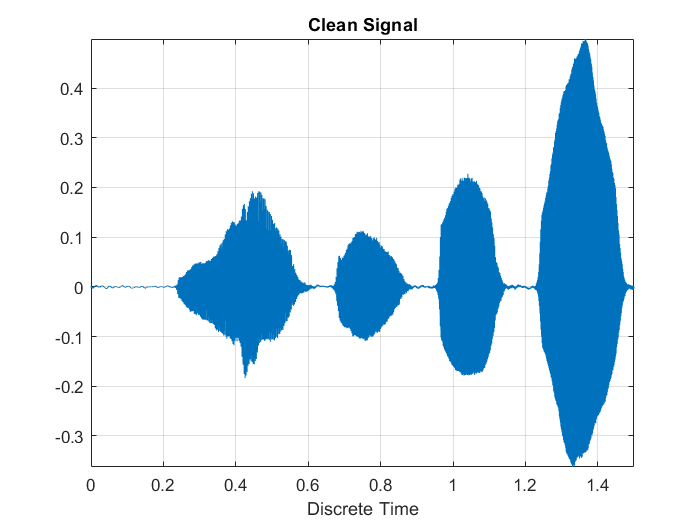

[voice,Fs] = audioread("singing.wav");
[ir, Fs2] = audioread("spokane_womans_club_ir.wav");

% soundsc(voice, Fs);

staccato = voice(1:ceil(1.5*Fs));

N = length(staccato);
Ts = 1/Fs;
time_axis = 0:Ts:(N-1)*Ts;

figure()
plot(time_axis,staccato)
title("Clean Signal")
xlabel("Discrete Time")
axis tight
grid on

#### Convolution with the loaded impulse response:

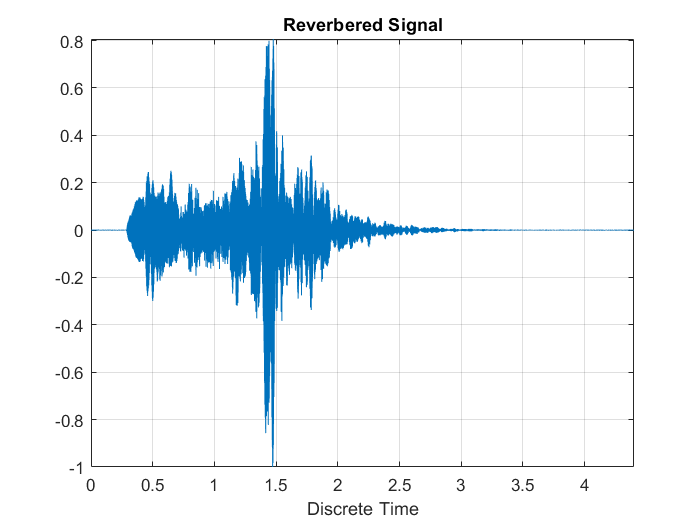

% x_left = conv(staccato, ir(:, 1));
% x_right = conv(staccato, ir(:, 2));
% 
% x = [x_left, x_right];
% 
% % Normalize the obtained audio
% x = x / max(abs(x));
% 
% % Shorten the file
% x = x(1:ceil(4.4*Fs));
% 
% audiowrite(['reverbered_voice','.wav'], x, Fs);

[x, Fs] = audioread("reverbered_voice.wav");

% soundsc(x, Fs);
x_mono = sum(x,2);
N = length(x_mono);

Ts = 1/Fs;
time_axis = 0:Ts:(N-1)*Ts;

figure()
plot(time_axis,x_mono)
title("Reverbered Signal")
xlabel("Discrete Time")
axis tight
grid on

## CEPSTRAL ANALYSIS

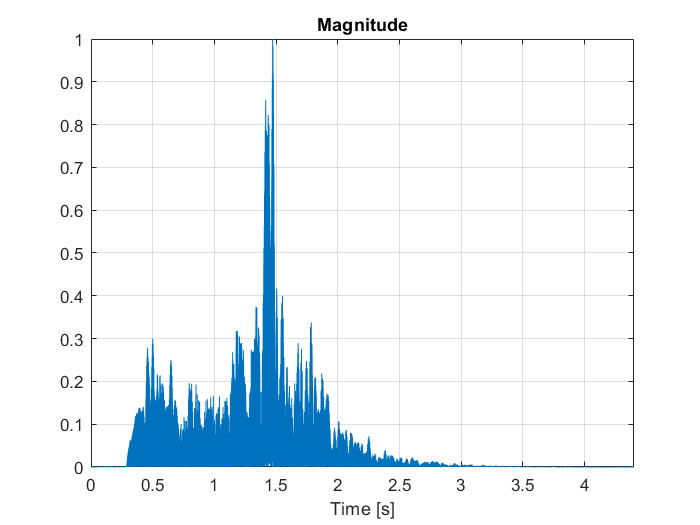

figure()
magnitude = abs(x_mono);
plot(time_axis,magnitude)
title("Magnitude")
xlabel("Time [s]")
axis tight
grid on


% SEGMENTATION by eye
segments = [[0.23, 0.62];
            [0.66, 0.89];
            [0.95, 1.15];
            [1.22, 1.5]];

limits_idx = zeros(4,2);
[~,start_idx] = min(abs(time_axis - segments(:,1)),[],2);
[~,stop_idx] = min(abs(time_axis - segments(:,2)),[],2);
limits_idx(:,1) = start_idx; limits_idx(:,2) = stop_idx;

durations = diff(limits_idx,1,2)

durations =        18720
       11040
        9600
       13440


durations = 2.^nextpow2(durations)

durations =        32768
       16384
       16384
       16384


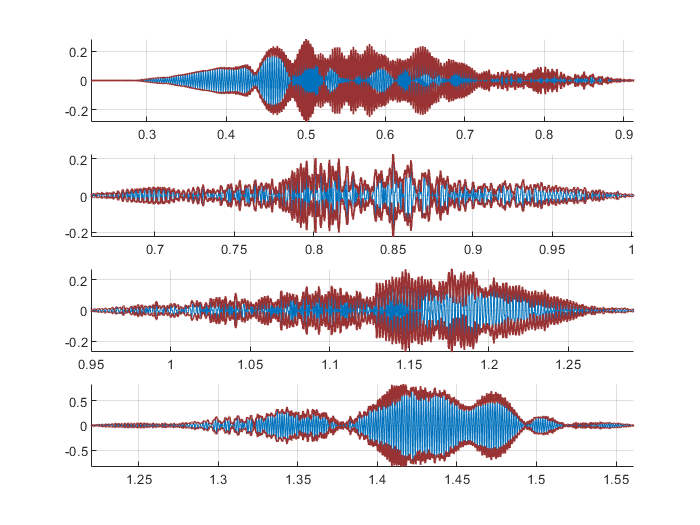

max_frame_size = max(durations);
frames = zeros(4,max_frame_size);
limits_idx(:,2) = limits_idx(:,1) + durations;


figure()
for i = 1:4
    t = time_axis(limits_idx(i,1) : limits_idx(i,2) - 1);
    frame = x_mono(limits_idx(i,1) : limits_idx(i,2) - 1);
    frames(i, 1:durations(i)) = frame;
    
    
    % exponential windowing and weighting (as exposed in the articles)
    exp_window = expwin(durations(i), 0.996*pi);
    frame = frame .* exp_window;
%     movavgExp = dsp.MovingAverage('Method', 'Exponential weighting', 'ForgettingFactor', 0.1);
%     frame = movavgExp(frame);

    env = abs(hilbert(frame));
    
    plot_param = {'-','Color', [0.6 0.2 0.2],'Linewidth',1}; 
    
    subplot(4,1,i)
    hold on
    plot(t,frame)
    plot(t,[-1;1]*env',plot_param{:})
    hold off
    axis tight; grid on
    axis tight
end

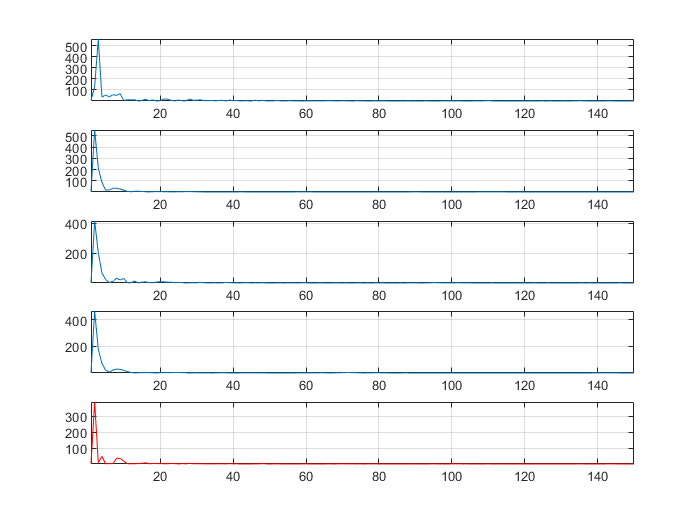

% CEPSTRUM --> Non funziona un cazzo
figure()
max_quefrency_bin = 150;
avg_Cepstrum = zeros(4,max_quefrency_bin);

for i = 1:4
%     X = fft(frames(i,:));
%     L = length(X);
%     X = X(1 : L/2 + 1);
%     Cepstrum = ifft(log(X));

% complex cepstrum
    Cepstrum = cceps(frames(i, :));
    Cepstrum = Cepstrum(1:max_quefrency_bin);
    quefrency = 1:length(Cepstrum);
    subplot(5,1,i)
    plot(quefrency,abs(Cepstrum))
    avg_Cepstrum(i,:) = Cepstrum;
    grid on; axis tight
end

avg_Cepstrum = sum(avg_Cepstrum,1)/4;
subplot(5,1,5)
plot(quefrency, abs(avg_Cepstrum),'r')
grid on; axis tight